# Script d2017_10_25_gyak6_PID

File:   d2017_10_25_gyak6_PID.m

Author: Peter Polcz <ppolcz@gmail.com>

Created on 2017. October 25.

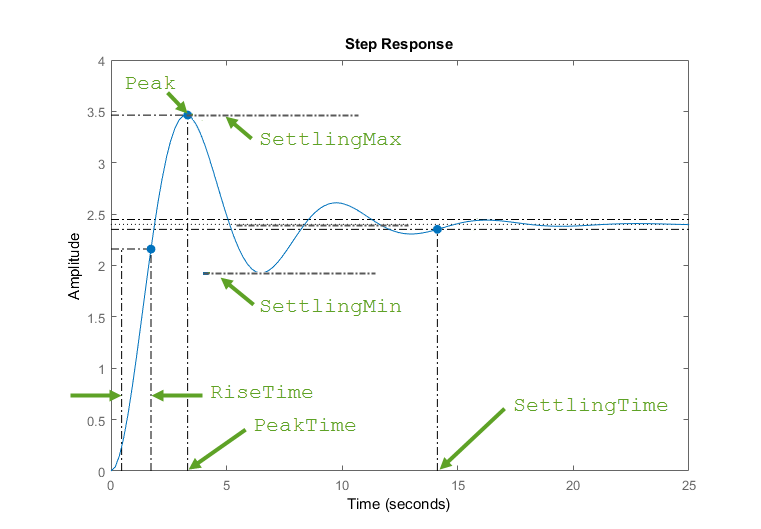

## Reference tracking using PID controller. Signal attributes


$$H(s) = \frac{s^2 + 3s + 2}{s^3 + 2s^2 - 6s + 8}$$


H = tf([1 3 2],[1 2 -6 8]);

We design a PID controller $C(s)$.

C = pidtune(H,'pid');

The resulting system: $H_e(s) = \frac{C(s) H(s)}{1 + C(s) H(s)}$.

He = C*H / (1 + C*H);

Generate the step response function.

T = 10;
t = linspace(0,T,1000);

u = t*0;
u(t > T/20) = 1;

Simulate

y = lsim(He,u,t);

Rise time plot

ans = 0.0810

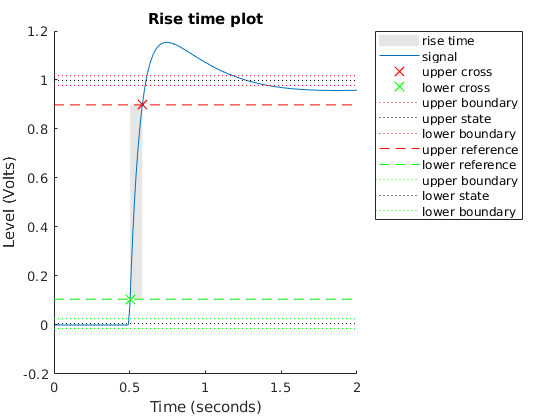

figure, risetime(y,t), xlim([0 T/5]), title 'Rise time plot'

Settling time plot

ans = 2.4259

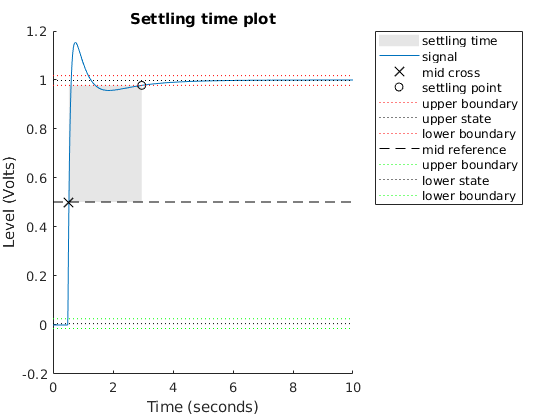

figure, settlingtime(y,t,2.68), title 'Settling time plot'

Overshoot plot

ans = 15.6977

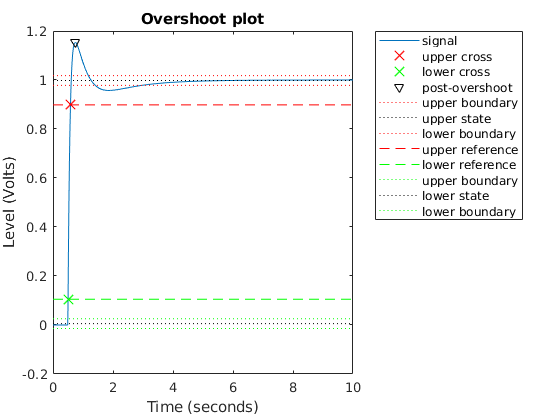

figure, overshoot(y,t), title 'Overshoot plot'

Undershoot plot

ans = -1.0401

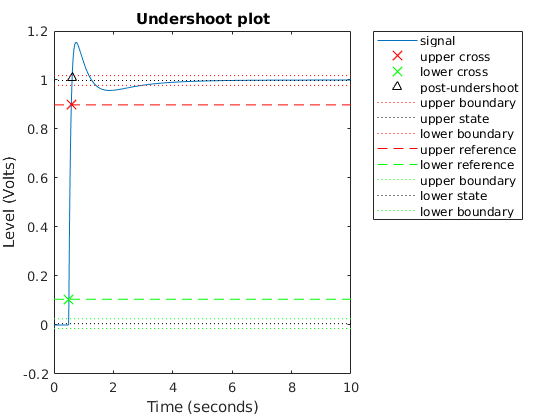

figure, undershoot(y,t), title 'Undershoot plot'

Step info

stepinfo(y,t)

ans = struct with fields:
        RiseTime: 0.0816
    SettlingTime: 3.0669
     SettlingMin: 0.9335
     SettlingMax: 1.1536
       Overshoot: 15.3693
      Undershoot: 0
            Peak: 1.1536
        PeakTime: 0.7407

## Oscillating system. Undershoot


$$H(s) = \frac{1}{(s+1)(s^2 + 0.6s + 1.09)}$$


s = tf('s');
H = 1 / ( (s+0.3-1i)*(s+0.3+1i)*(s+1) );
[y,t] = step(H);

undershoot(y,t)

ans = 9.4668

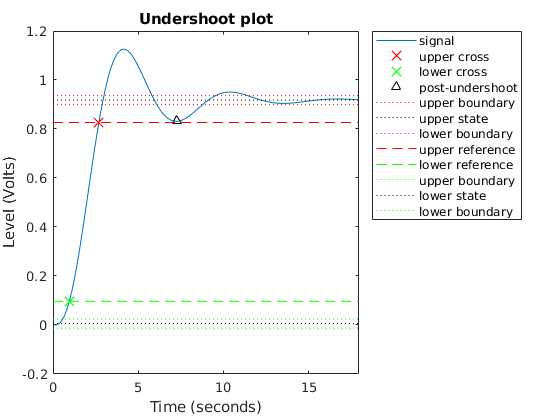

title 'Undershoot plot'

## Settling time of a noisy signal

load('transitionex.mat', 'x')
[s,slev,sinst] = settlingtime(x,10)

s = 1.8901

slev = 2.2400

sinst = 23.3901

ans = 1.8901

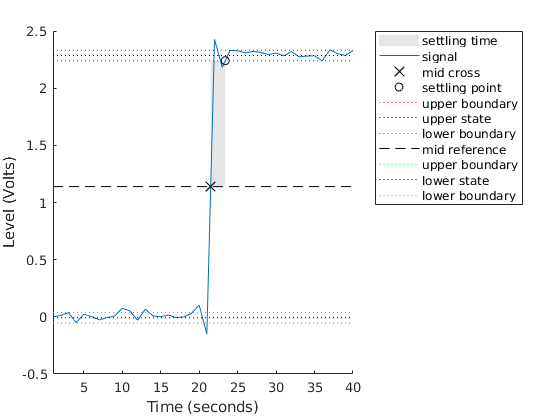

settlingtime(x,10)

## PID Tuner


$$H(s) = \frac{s^2 + 3s + 2}{s^3 + 2s^2 - 6s + 8}$$


The resulting system: $H_e(s) = \frac{C(s) H(s)}{1 + C(s) H(s)}$.

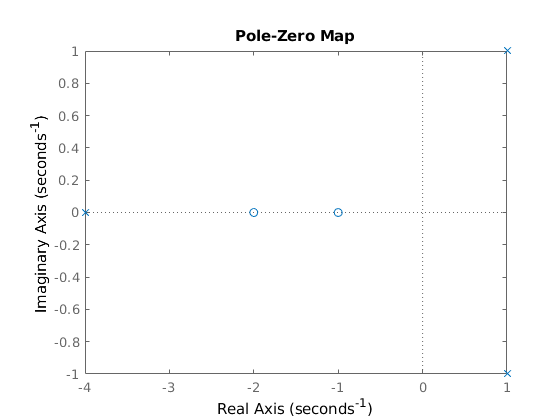

H = tf([1 3 2],[1 2 -6 8]);
figure(1), pzmap(H)

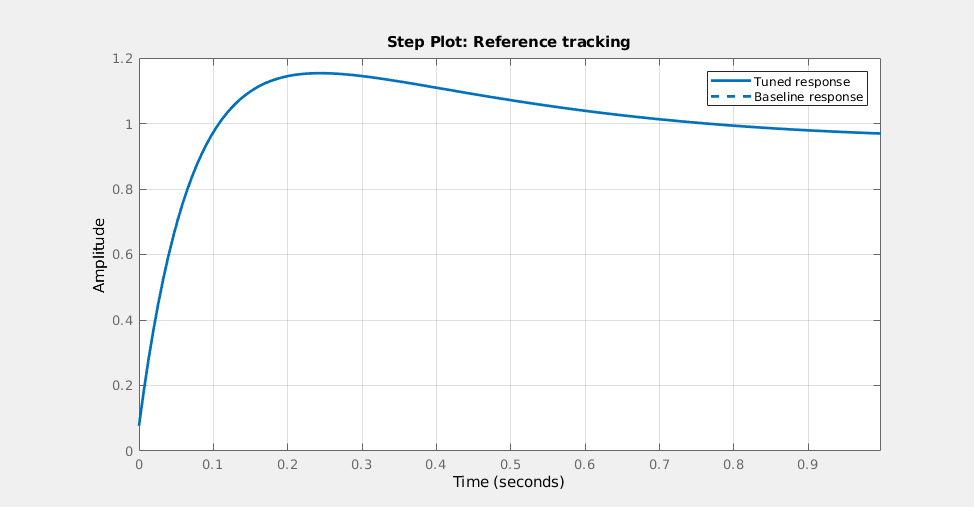

C = pidtune(H,'pid');
pidTuner(H,C)